## Aufgabe 1: Variable

#### a)

f0 = 20;
2.5 * sqrt(3) * sin(2*pi*(33.3+ f0))

ans = 4.1182

#### b)

a = 3+1i;
abs(a)

ans = 3.1623

rad2deg(angle(a))

ans = 18.4349

b = -2-1i;
abs(b)

ans = 2.2361

rad2deg(angle(b))

ans = -153.4349

#### c)

v = [1, 2, -3, 4+1i];

#### d)

omega = transpose(v)

omega =    1.0000 + 0.0000i
   2.0000 + 0.0000i
  -3.0000 + 0.0000i
   4.0000 + 1.0000i


#### e)

M = [1,0,0; 0, 1i, 1; 1i, 1i+1, -3;]

M =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i
   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i


#### f)

V = [M, M; M, M]

V =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i
   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i
   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i


#### g)

z4 = V(4, 1:6)

z4 =      1     0     0     1     0     0


#### h)

V(4,2) = 5.8

V =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i
   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i
   1.0000 + 0.0000i   5.8000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i
   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 1.0000i  -3.0000 + 0.0000i


#### i)

sprintf("Blindleistung = %d var", 40)

ans = "Blindleistung = 40 var"

## Aufgabe 2: Mathematische Operationen

#### a)

A = [1, 2; 3, 4]

A =      1     2
     3     4


B = [1, 2; 2, 4]

B =      1     2
     2     4


#### b)

inv(A)

ans =    -2.0000    1.0000
    1.5000   -0.5000


inv(B)

ans =    Inf   Inf
   Inf   Inf


#### c)

A.*3

ans =      3     6
     9    12


#### d)

A*B

ans =      5    10
    11    22


#### e)

A.*B

ans =      1     4
     6    16


#### f)

t = [0:0.1:0.5]

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000


for i = [1:1:6]
        y(1, i) = sin(2*pi*6*t(1, i)) + cos(2*pi*3*t(1, i))+exp(-0.1*t(1, i));
end
for i = [1:1:6]
    fprintf("y%d = %d\n", i, y(1, i))
end

y1 = 2
y2 = 9.324759e-02
y3 = 1.122238e+00
y4 = 8.284060e-01
y5 = 1.857592e+00
y6 = -4.877058e-02


#### g)

for i = [1:1:6]
    z(1,i) = sin(2*pi*6*t(1, i)) * cos(2*pi*3*t(1, i)) * exp(-0.1 * t(1, i));
end
for i = [1:1:6]
    fprintf("z%d = %d\n", i, z(1, i))
end

z1 = 0
z2 = 1.798283e-01
z3 = -7.541853e-01
z4 = -7.466811e-01
z5 = 1.745136e-01
z6 = 6.989520e-16


#### i)

TAB = transpose([t; y; z])

TAB =          0    2.0000         0
    0.1000    0.0932    0.1798
    0.2000    1.1222   -0.7542
    0.3000    0.8284   -0.7467
    0.4000    1.8576    0.1745
    0.5000   -0.0488    0.0000


#### j)

p = [1024, 1000, 100, 2, 1, 1/sqrt(2)]

p = 	1.0e+03 *

    1.0240    1.0000    0.1000    0.0020    0.0010    0.0007


p_db = 10 * log10(p)

p_db =    30.1030   30.0000   20.0000    3.0103         0   -1.5051


## Aufgabe 3: Grafische Ausgabe

#### a)

t2 = [0:0.01:2];
u1 = 3*sin(2*pi*3*t2);
u2 = 5*cos(2*pi*t2*5 - deg2rad(30));
u3 = 6*exp(-t2/2);

#### b)

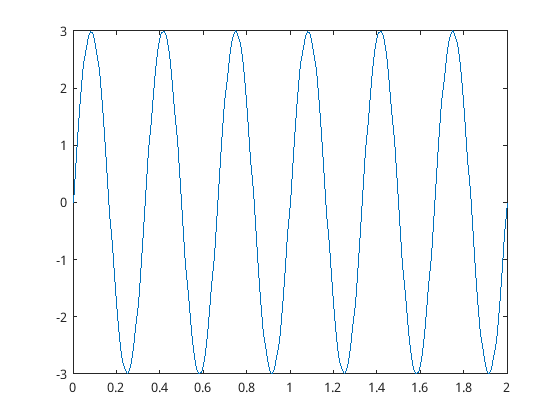

close all;
f1 = figure;
plot(t2, u1)
saveas(gcf, "u1.png")

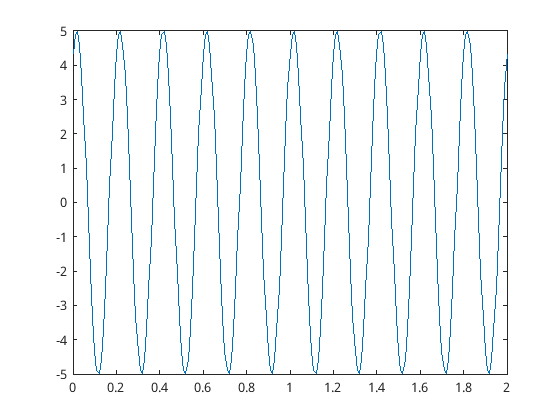

f2 = figure;
plot(t2, u2)
saveas(gcf, "u2.png")

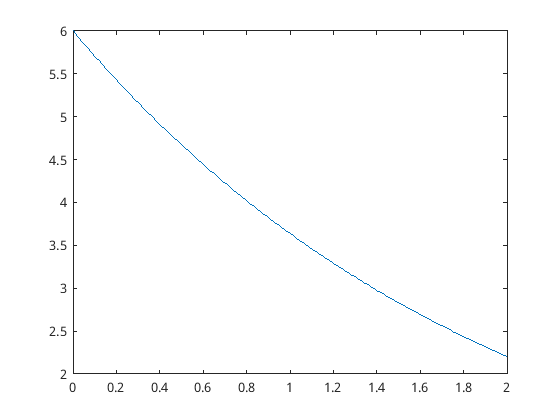

f3 = figure;
plot(t2, u3)
saveas(gcf, "u3.png")

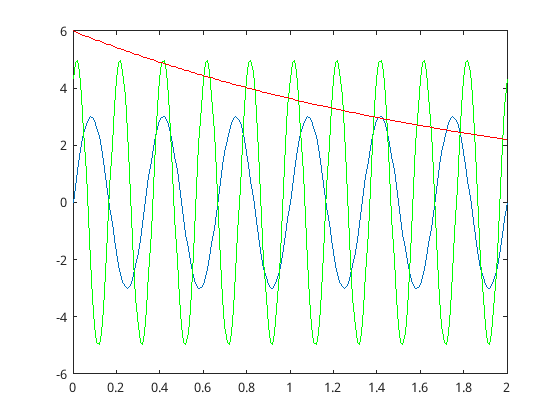

figure;
plot(t2, u1, t2, u2, 'g', t2, u3, 'r')
saveas(gcf, "triplePlot.png")

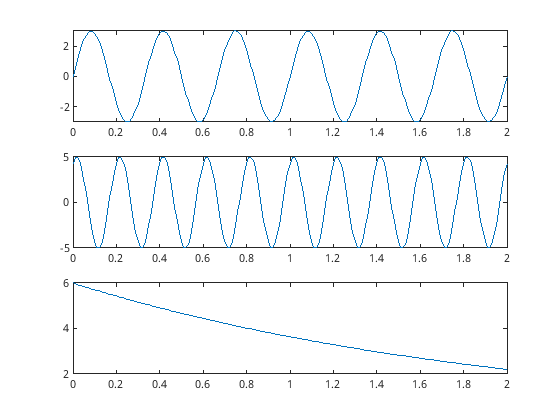

figure; 
subplot(3, 1, 1);
plot(t2, u1)

subplot(3, 1, 2);
plot(t2, u2)

subplot(3, 1, 3);
plot(t2, u3)
saveas(gcf, "subplot.png")

#### c)

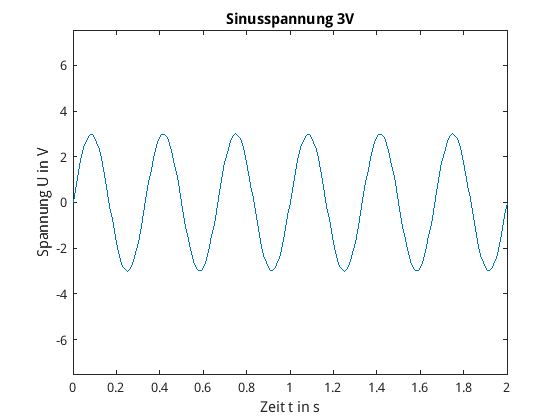

close all;
figure
plot(t2, u1)

title("Sinusspannung 3V")
xlabel("Zeit t in s")
ylabel("Spannung U in V")

ylim([-7.5, 7.5])
saveas(gcf, "Sinusspannung3V.png")

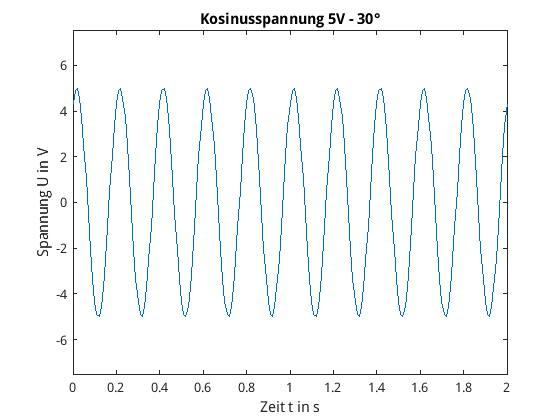

figure
plot(t2, u2)

title("Kosinusspannung 5V - 30°")
xlabel("Zeit t in s")
ylabel("Spannung U in V")

ylim([-7.5, 7.5])
saveas(gcf, "Kosinusspannung5V.png")

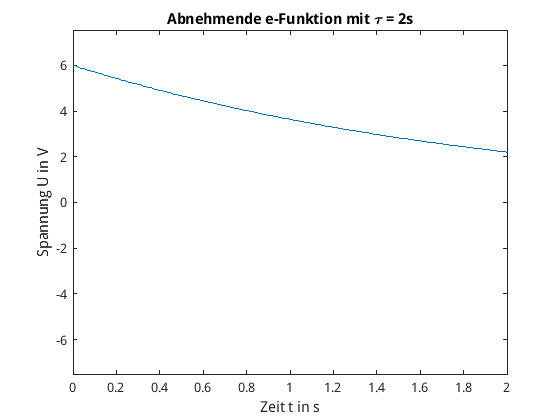

figure
plot(t2, u3)

title("Abnehmende e-Funktion mit \tau = 2s")
xlabel("Zeit t in s")
ylabel("Spannung U in V")

ylim([-7.5, 7.5])
saveas(gcf, "eFunk2s.png")